clearvars
close all

osrm_data_sp = load('output_data\osrm_output_with_speed.mat').out;
aug_data = load('output_data\aug_output.mat').aug_data;
segments = load('input_data\osm.mat').osm;
markers = load('input_data\markers.mat').markers;
% adding distance from origin column to aug_out
[~,b] = ismember(aug_data.segment_id,segments.segment_id);
aug_data.distance_from_start = segments.distance_from_start(b);

corridor_length = 1e-3 * max(sum(segments(segments.dir==2,:).calc_length) , sum(segments(segments.dir==1,:).calc_length));
osrm_data_sp.Properties.VariableNames{10} = 'dir';
osrm_data_sp.Properties.VariableNames{11} = 'segment_id';
aug_data.Properties.VariableNames{2} = 'time';
osrm_data_sp.Properties.VariableNames{4} = 'time';

aux_segments = unique(aug_data.segment_id);
filter = NaN(size(aug_data,1),1);
for i=1:1:length(aux_segments)
    filter(aug_data.segment_id == aux_segments(i)) = isoutlier(aug_data(aug_data.segment_id == aux_segments(i),:).speed,'quartiles');
end
aug_data.filter = ~logical(filter);
size(aug_data,1);
sum(filter);

aux_segments = unique(osrm_data_sp.segment_id);
filter = NaN(size(osrm_data_sp,1),1);
for i=1:1:length(aux_segments)
    filter(osrm_data_sp.segment_id == aux_segments(i)) = isoutlier(osrm_data_sp(osrm_data_sp.segment_id == aux_segments(i),:).speed,'quartiles');
end
osrm_data_sp.filter = ~logical(filter);
size(osrm_data_sp,1);
sum(filter);

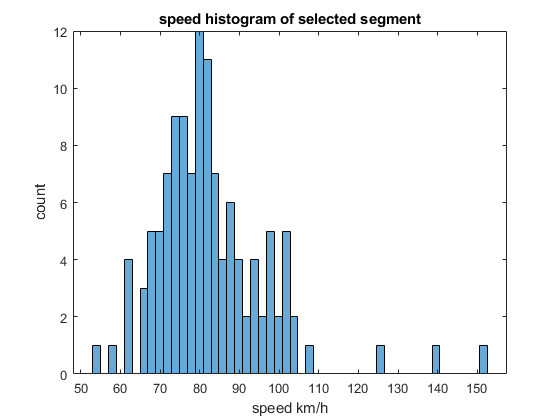

% selected_segment_id = 52;
selected_segment_id = 300;


data = aug_data(aug_data.segment_id == selected_segment_id,:);

data = data(~isnan(data.speed),:); %nan'ları sil

data = sortrows(data,"time"); % time'a göre sort

histogram(data.speed,50)
title('speed histogram of selected segment')
ylabel('count')
xlabel('speed km/h')

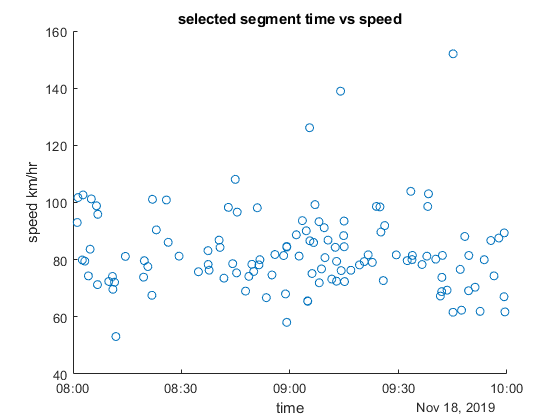

scatter(data.time, data.speed)
xlabel('time')
ylabel('speed km/hr')
title('selected segment time vs speed')

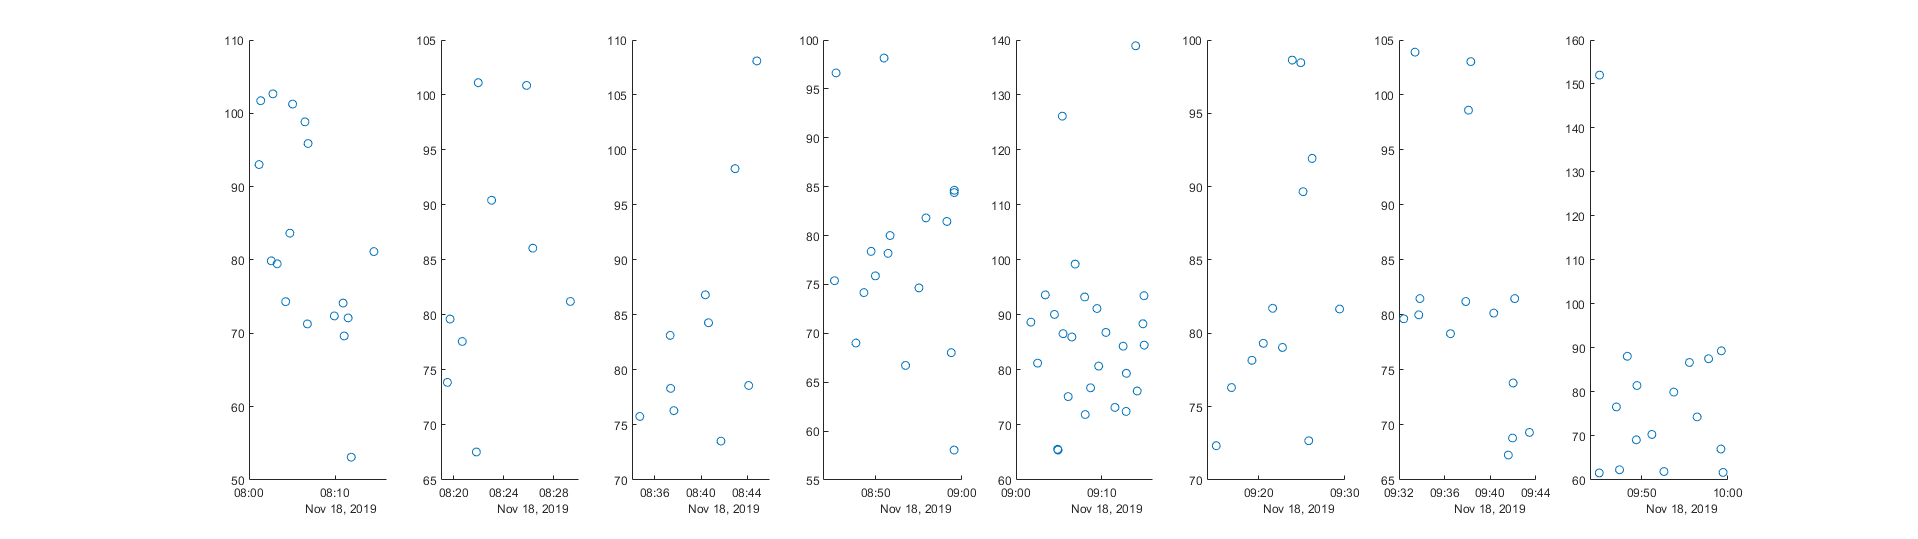

time_1 = datetime({'2019-11-18 08:00:00'});
time_2 = datetime({'2019-11-18 10:00:00'});
aux_time = time_1:minutes(15):time_2;
% dir_chosen = 2;
h=figure();
for i=1:1:length(aux_time)-1
    ax1 = subplot(1, length(aux_time)-1, i);
%     index = aug_data.dir == dir_chosen & aug_data.time >= aux_time(i) & aug_data.time < aux_time(i+1) & aug_data.filter;
%     boxchart(ax1, double(aug_data.segment_id(index)) ,aug_data.speed(index),"MarkerStyle",'.','MarkerColor','red')
    index = data.time >= aux_time(i) & data.time < aux_time(i+1);
    scatter(data.time(index), data.speed(index));
%     min_x = min(double(aug_data.segment_id(index)));
%     max_x = max(double(aug_data.segment_id(index)));
%     ax1.XLim = [ min_x - 1 , max_x + 1];
%     ax1.XTick = int64(linspace(min_x,max_x,10));
%     ax1.XDir = "reverse";
%     title(['AUG* ',datestr(aux_time(i)), '---', datestr(aux_time(i+1)),'  ','direction = ', num2str(dir_chosen), 'segment id vs speed boxplot ndata = ',num2str(sum(index))]);
%     ylim([0 200]);
% %     yLimits = get(ax1,'YLim');
%     line(ax1,[markers.segment_id(markers.dir == dir_chosen),markers.segment_id(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
end
% text(ax1, double(markers.segment_id(markers.dir == dir_chosen)), -0.6*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);
set(h,'Units','normalized','Position',[0 0 1 0.5]);

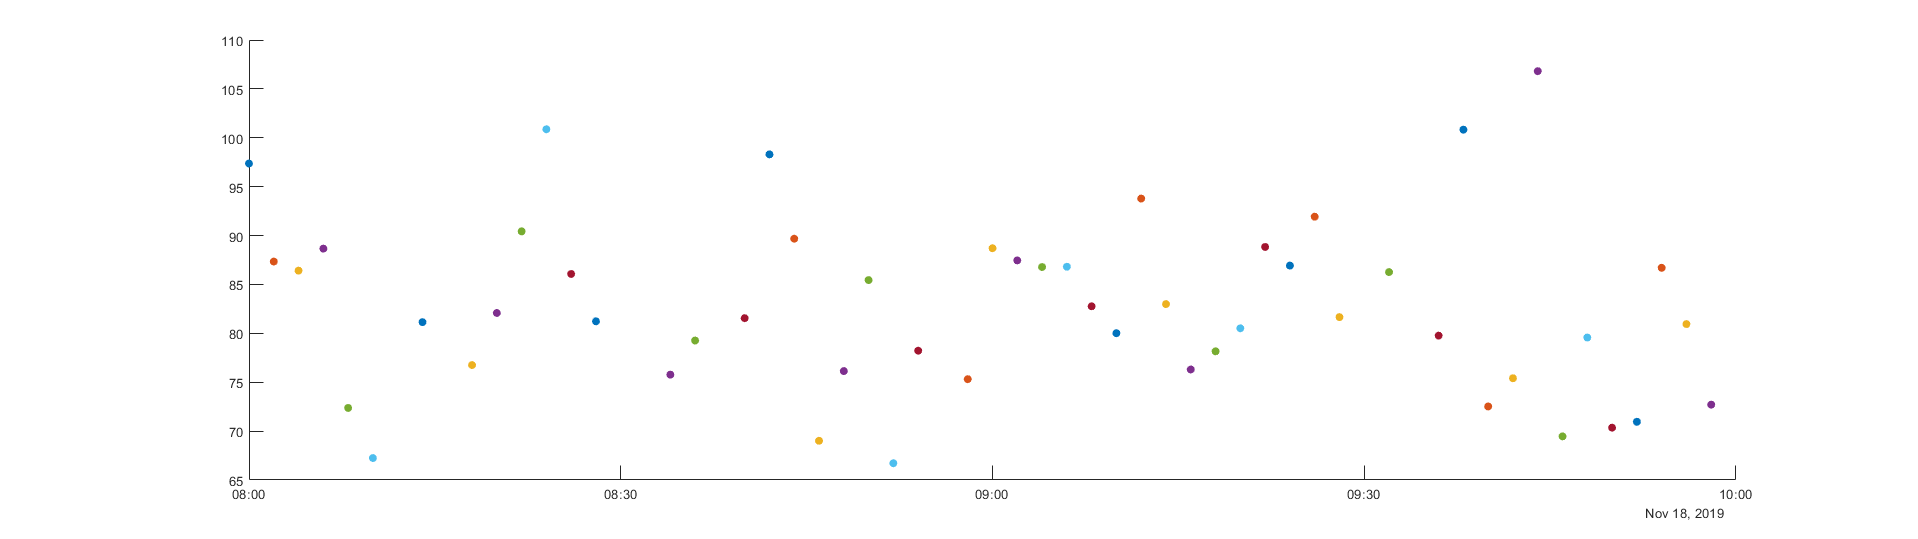

time_1 = datetime({'2019-11-18 08:00:00'});
time_2 = datetime({'2019-11-18 10:00:00'});
aux_time = time_1:minutes(2):time_2;
% dir_chosen = 2;
h=figure();
ax1 = subplot(1,1,1);
for i=1:1:length(aux_time)-1
%     ax1 = subplot(1, length(aux_time)-1, i);
%     index = aug_data.dir == dir_chosen & aug_data.time >= aux_time(i) & aug_data.time < aux_time(i+1) & aug_data.filter;
%     boxchart(ax1, double(aug_data.segment_id(index)) ,aug_data.speed(index),"MarkerStyle",'.','MarkerColor','red')
    index = data.time >= aux_time(i) & data.time < aux_time(i+1);
    scatter(ax1,aux_time(i), mean(data.speed(index)),'filled');
    hold(ax1,'on');
%     min_x = min(double(aug_data.segment_id(index)));
%     max_x = max(double(aug_data.segment_id(index)));
%     ax1.XLim = [ min_x - 1 , max_x + 1];
%     ax1.XTick = int64(linspace(min_x,max_x,10));
%     ax1.XDir = "reverse";
%     title(['AUG* ',datestr(aux_time(i)), '---', datestr(aux_time(i+1)),'  ','direction = ', num2str(dir_chosen), 'segment id vs speed boxplot ndata = ',num2str(sum(index))]);
%     ylim([0 200]);
% %     yLimits = get(ax1,'YLim');
%     line(ax1,[markers.segment_id(markers.dir == dir_chosen),markers.segment_id(markers.dir == dir_chosen)] , yLimits,'LineStyle','--','LineWidth',0.1);
end
% text(ax1, double(markers.segment_id(markers.dir == dir_chosen)), -0.6*repmat(yLimits(2),sum((markers.dir == dir_chosen)),1),(markers.names(markers.dir == dir_chosen)),'Rotation',90);
set(h,'Units','normalized','Position',[0 0 1 0.5]);


% speed labels (hmm states)

data.speed_labels = NaN(size(data,1),1);

% 
% data.speed_labels(data.speed >= 110) = 1;
% data.speed_labels(data.speed >= 100 & data.speed < 110) = 2;
% data.speed_labels(data.speed >= 90 & data.speed < 100) = 3;
% data.speed_labels(data.speed >= 80 & data.speed < 90) = 4;
% data.speed_labels(data.speed >= 70 & data.speed < 80) = 5;
% data.speed_labels(data.speed >= 60 & data.speed < 70) = 6;
% data.speed_labels(data.speed >= 50 & data.speed < 60) = 7;
% data.speed_labels(data.speed < 50) = 8;

data.speed_labels(data.speed >= 110) = 1;
data.speed_labels(data.speed >= 80 & data.speed < 110) = 2;
% data.speed_labels(data.speed >= 90 & data.speed < 100) = 3;
data.speed_labels(data.speed >= 50 & data.speed < 80) = 3;
% data.speed_labels(data.speed >= 70 & data.speed < 80) = 5;
% data.speed_labels(data.speed >= 50 & data.speed < 70) = 4;
% data.speed_labels(data.speed >= 50 & data.speed < 60) = 7;
data.speed_labels(data.speed < 50) = 4;


n_observed_states = size(unique(data.speed_labels),1);
% initial guess of state transition matrix

n_hidden_states = 3;
% tr_guess = ones(n_hidden_states,n_hidden_states) / n_hidden_states;

tr_guess =[0.90, 0.10;
            0.20, 0.80];

% tr_guess = tr_guess + (1-eye(n_hidden_states)) * 0.5/3;
% emis = ones(n_hidden_states,n_observed_states) / n_observed_states;

[a,b] = groupcounts(data.speed_labels);

% emis = repmat(transpose(a ./ sum(a)),n_hidden_states,1) .* rand(n_hidden_states, 1)
emis = [0.0566, 0.94,   0.01,      0.01;
        0.01,    0.01,  0.92,   0.0778]

emis =     0.0566    0.9400    0.0100    0.0100
    0.0100    0.0100    0.9200    0.0778



% emis = [0.05, 0.4,   0.5,      0.05;
%         0.05,    0.5,  0.35,   0.1]
% emis = rand(n_hidden_states,n_observed_states)

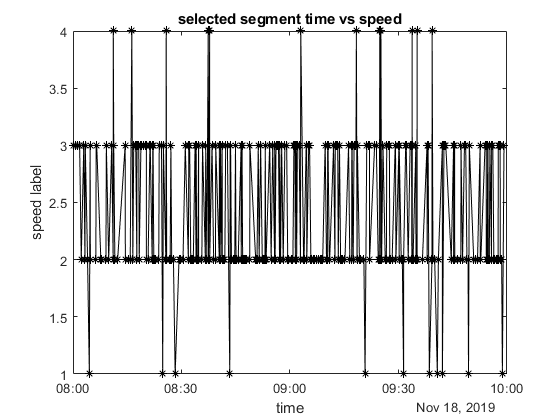

plot(data.time, data.speed_labels, '-*k')
xlabel('time')
ylabel('speed label')
title('selected segment time vs speed')

[estTR,estE] = hmmtrain(data.speed_labels,tr_guess,emis,"Maxiterations",10000,"Tolerance",1e-11,"Verbose",true);%,"Algorithm","Viterbi");

Relative Changes in Log Likelihood, Transition Matrix and Emission Matrix
   Iteration       Log Lik    Transition     Emmission
       2           0.25866   1.11022e-16   1.19696e-16
       3                 0   3.05311e-16   8.32667e-17
Algorithm converged after 3 iterations.



estTR

estTR =     0.6127    0.3873
         0    1.0000


estE

estE =     0.0507    0.8602    0.0591    0.0300
    0.0016    0.0016    0.9558    0.0411




[estTR,estE] = hmmtrain(data.speed_labels,estTR,estE);

estTR

estTR =     0.8890    0.1110
         0    1.0000



estE

estE =     0.0349    0.5526    0.3918    0.0207
    0.0055    0.3280    0.5232    0.1433


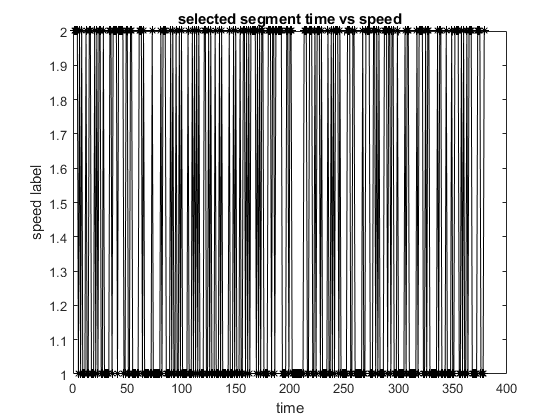

% STATES = hmmviterbi(data.speed_labels,estTR,estE)
tr_guess =[0.95, 0.05;
            0.70, 0.30];

aq = hmmviterbi(data.speed_labels,tr_guess,emis);

plot(aq, '-*k')
xlabel('time')
ylabel('speed label')
title('selected segment time vs speed')


[ESTTR,ESTEMIT] = hmmtrain(data.speed_labels,tr_guess,emis)

ESTTR =     0.6527    0.3473
         0    1.0000


ESTEMIT =     0.0481    0.8081    0.1066    0.0373
    0.0008    0.0009    0.9696    0.0287


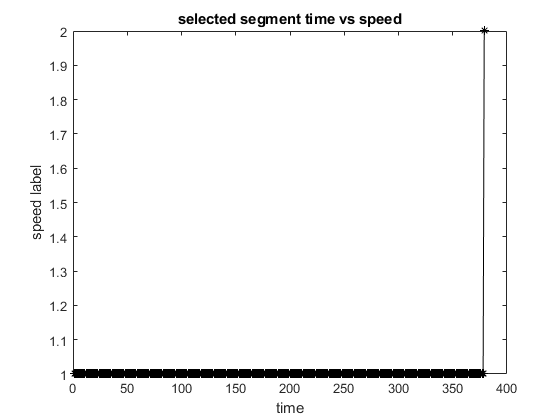

% ESTTR(2,:) = [0.4,0.6]
aq = hmmviterbi(data.speed_labels,ESTTR,ESTEMIT);

plot(aq, '-*k')
xlabel('time')
ylabel('speed label')
title('selected segment time vs speed')